# RBE 501 Final Exam

Author: Keith Chester - kchester@wpi.edu

## A

In this problem, we are calculating the Lagrangian of the robot arm presented.

Here, we are using the DH convention to establish frames for the various joints and effector of the robot arm.

syms q1 q2 q3 m1 m2 m3 a b c real
arm = [
        struct("name", "joint1", "theta", q1, "a", 0, "d", 0, "alpha", 0, "mass", m1, "type", "revolute");
        struct("name", "joint2", "theta", 0, "a", 0, "d", a, "alpha", -pi/2, "mass", 0, "type", "fixed");
        struct("name", "joint3", "theta", 0, "a", 0, "d", b+q2, "alpha", -pi/2, "mass", m3, "type", "prismatic");
        struct("name", "ee", "theta", pi/2, "a", 0, "d", c+q3, "alpha", 0, "mass", m3, "type", "prismatic");
      ];

We have then a function, defined below, to generate the translations from the base frame to each of the defined frames.

Ts = get_base_transformations(arm);

Unfortunately the MATLAB symbolic engine creates several terms with extremely tiny coeffecients instead of zero, resulting in complex outputs that become impossible to simplify later on as you work with them. They also significantly slow down processing. For this reason we manually simplify the transforms here:

Ts{1} = [cos(q1) -sin(q1) 0 0; sin(q1) cos(q1) 0 0;  0 0 1 0; 0 0 0 1;];
Ts{2} = [cos(q1) 0 -sin(q1) 0; sin(q1) 0 cos(q1) 0; 0 -1 0 a; 0 0 0 1];
Ts{3} = [cos(q1) sin(q1) 0 -sin(q1)*(b+q2); sin(q1) -cos(q1) 0 cos(q1)*(b+q2); 0 0 -1 a; 0 0 0 1;];
Ts{4} = [sin(q1) -cos(q1) 0 -sin(q1)*(b+q2); -cos(q1) -sin(q1) 0 cos(q1)*(b+q2); 0 0 -1 a-c-q3; 0 0 0 1;];


Rs = {Ts{1}(1:3,1:3), Ts{2}(1:3,1:3), Ts{3}(1:3,1:3)};

Here we determine the location of the center of mass within the base frame.

x_m1 = Ts{2}(1:4, 4);
x_m2 = x_m1;
x_m3 = Ts{4}(1:4,4);

Now that we have the locations of the center of mass and translations and forward kinematics of the robot arm defined, we will now need to solve for each $J_{v_{\textrm{ci}} }$, where:


$$J_{v_{\mathrm{ci}} } =\left\lbrack \begin{array}{ccc}
\frac{d}{\mathrm{d}q_1 }x_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_2 }x_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_3 }x_{\mathrm{mi}} \\
\frac{d}{\mathrm{d}q_1 }y_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_2 }y_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_3 }y_{\mathrm{mi}} \\
\frac{d}{\mathrm{d}q_1 }z_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_2 }z_{\mathrm{mi}}  & \frac{d}{\mathrm{d}q_3 }z_{\mathrm{mi}} 
\end{array}\right\rbrack$$


J_vc1 = simplify(jacobian(Ts{1}(1:3,4), [q1 q2 q3]));
J_vc2 = simplify(jacobian(Ts{2}(1:3,4), [q1 q2 q3]));
J_vc3 = simplify(jacobian(Ts{3}(1:3,4), [q1 q2 q3]));

$J_{w_i } =\left\lbrack \begin{array}{ccc}
z_i  & 0 & 0
\end{array}\right\rbrack$ due to revolute

J_w1 = [Rs{1}(1:3, 3) zeros(3,2)];
J_w2 = [Rs{1}(1:3, 3) zeros(3,2)];
J_w3 = [Rs{1}(1:3, 3) zeros(3,2)];

Here we establish the inertial matricies. To simplify calculations, we assume that any value outside of the diagonal is zero.


$$\left(\begin{array}{ccc}
{\mathrm{ix}}_1  & i_{1,12}  & i_{1,13} \\
i_{1,12}  & {\mathrm{iy}}_1  & i_{1,23} \\
i_{1,13}  & i_{1,23}  & {\mathrm{iz}}_1 
\end{array}\right)$$


syms ix1 iy1 iz1 i1_12 i1_13 i1_23
% I1 = [ix1 i1_12 i1_13; i1_12 iy1 i1_23; i1_13 i1_23 iz1;];
I1 = [ix1 0 0; 0 iy1 0; 0 0 iz1;];

syms ix2 iy2 iz2 i2_12 i2_13 i2_23
% I2 = [ix2 i2_12 i2_13; i2_12 iy2 i2_23; i2_13 i2_23 iz2;]
I2 = [ix2 0 0; 0 iy2 0; 0 0 iz2;];

syms ix3 iy3 iz3 i3_12 i3_13 i3_23
% I3 = [ix3 i3_12 i3_13; i3_12 iy3 i3_23; i3_13 i3_23 iz3;]
I3 = [ix3 0 0; 0 iy3 0; 0 0 iz3;];


$$v_i =m_i *J_{v_{\mathrm{ci}} }^T *J_{v_{\mathrm{ci}} }$$


v_1 = simplify(arm(1).mass*transpose(J_vc1)*J_vc1);
v_2 = simplify(arm(2).mass*transpose(J_vc2)*J_vc2);
v_3 = simplify(arm(3).mass*transpose(J_vc3)*J_vc3);


$$\omega_i =J_{\omega_i }^T *R_i *I_i *R_i^T *J_{\omega_i }$$


w_1 = simplify(vpa(transpose(J_w1)*Rs{1}*I1*transpose(Rs{1})*J_w1, 4));
w_2 = simplify(vpa(transpose(J_w2)*Rs{2}*I2*transpose(Rs{2})*J_w2, 4));
w_3 = simplify(vpa(transpose(J_w3)*Rs{3}*I3*transpose(Rs{3})*J_w3, 4));

D is the summation of the v_i and w_i parts calculated above.


$$D=\sum v_i +\sum \omega_i$$


D = simplify(v_1 + v_2 + v_3 + w_1 + w_2 + w_3)

$$D = \left(\begin{array}{ccc} {\mathrm{iy}}_{2}+{\mathrm{iz}}_{1}+{\mathrm{iz}}_{3}+m_{3}\,{\left(b+q_{2}\right)}^{2} & 0 & 0\\ 0 & m_{3} & 0\\ 0 & 0 & 0 \end{array}\right)$$

We solve for Ckj via the following formulas:


$$C_{\mathrm{ijk}} =\frac{1}{2}\sum_1^n \sum_1^n \sum_1^n \frac{\partial }{\partial q_i }d_{\mathrm{kj}} +\frac{\partial }{\partial q_j }d_{\mathrm{ki}} -\frac{\partial }{\partial q_k }d_{\mathrm{ij}}$$



$$C_{\mathrm{kj}} =\sum_{i=1}^n C_{\mathrm{ijk}} \dot{q_i }$$


C_ijk = sym(zeros(3,3,3));

for i = 1:3
    for j = 1:3
        for k = 1:3
            
            d_kj = D(k,j);
            d_ki = D(k, i);
            d_ij = D(i, j);
            
            delta_d_kj = diff(d_kj, get_q_i(i));
            delta_d_ki = diff(d_ki, get_q_i(j));
            delta_d_ij = diff(d_ij, get_q_i(k));
            
            C_ijk(i, j, k) = 0.5*(delta_d_kj + delta_d_ki - delta_d_ij);
            
        end
    end
end

C_kj = sym(zeros(3,3));

for j = 1:3
    for k = 1:3
        for i = 1:3
            C_kj(k, j) = C_kj(k,j) + (C_ijk(i, j, k) * get_q_i_dot(i));
        end
    end
end

Thus our resulting values are:

C_kj

$$C\_kj = \left(\begin{array}{ccc} \frac{m_{3}\,\mathrm{q2dot}\,\left(2\,b+2\,q_{2}\right)}{2} & \frac{m_{3}\,\mathrm{q1dot}\,\left(2\,b+2\,q_{2}\right)}{2} & 0\\ -\frac{m_{3}\,\mathrm{q1dot}\,\left(2\,b+2\,q_{2}\right)}{2} & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Now we can solve for the gravity poriton of the compact form. First we define the potential energies for each center of mass - the $g_i$ term is equal to:


$$g_i =\frac{\partial }{\partial q_i }P_i$$



$$G=\left\lbrack \begin{array}{c}
g_1 \\
g_2 \\
g_3 
\end{array}\right\rbrack$$


g = 9.8;
P_1 = g*m1*x_m1(3);
P_2 = g*0*x_m2(3);
P_3 = g*m3*x_m3(3);
P = simplify(P_1 + P_2 + P_3);

g_1 = simplify(diff(P, q1));
g_2 = simplify(diff(P, q2));
g_3 = simplify(diff(P, q3));
G = [g_1; g_2; g_3;]

$$G = \left(\begin{array}{c} 0\\ 0\\ -\frac{49\,m_{3}}{5} \end{array}\right)$$

Finally we solve for the torques here, by combining the calculated coeffecients into compact form:


$$\tau =\left\lbrack \begin{array}{c}
\tau_1 \\
\tau_2 \\
\tau_3 
\end{array}\right\rbrack =D*\left\lbrack \begin{array}{c}
\ddot{q_1 } \\
\ddot{q_2 } \\
\ddot{q_3 } 
\end{array}\right\rbrack +C*\left\lbrack \begin{array}{c}
\dot{q_1 } \\
\dot{q_2 } \\
\dot{q_3 } 
\end{array}\right\rbrack +G$$


syms q1ddot q2ddot q3ddot q1dot q2dot q3dot
Lagrange_Tau = simplify(vpa(D*[q1ddot; q2ddot; q3ddot;] + C_kj*[q1dot; q2dot; q3dot;] + G, 3))

$$Lagrange\_Tau = \left(\begin{array}{c} \mathrm{q1ddot}\,\left({\mathrm{iy}}_{2}+{\mathrm{iz}}_{1}+{\mathrm{iz}}_{3}+m_{3}\,{\left(b+q_{2}\right)}^{2}\right)+m_{3}\,\mathrm{q1dot}\,\mathrm{q2dot}\,\left(2.0\,b+2.0\,q_{2}\right)\\ m_{3}\,\mathrm{q2ddot}-0.5\,m_{3}\,{\mathrm{q1dot}}^{2}\,\left(2.0\,b+2.0\,q_{2}\right)\\ -9.8000000000465661287307739257812\,m_{3} \end{array}\right)$$

## B

In this question we are attempting to solve for the system of torques for the robotic arm using the Newtonian method.

First we define some key rotations and transformations we'll be making use of.

R01 = Ts{1}(1:3,1:3);
R02 = Ts{2}(1:3,1:3);
R03 = Ts{3}(1:3,1:3);
R0ee = Ts{4}(1:3,1:3);

T12 = simplify(inv(Ts{1})*Ts{2});
T23 = simplify(inv(Ts{2})*Ts{3});
T3ee = simplify(inv(Ts{3})*Ts{4});

R12 = T12(1:3,1:3);
R23 = T23(1:3,1:3);
R3ee = T3ee(1:3,1:3);

We then utilize a recursive function, defined below, to discover the Newtonian angular velocity $\omega_i$.

For revolute joints:

$\omega_i ={\left(R_i^{i-1} \right)}^T \omega_{i-1} +b_i \dot{q_i }$ where $b_i ={\left(R_i^0 \right)}^T z_{i-1}$

For prismatic joints:


$$\omega_i ={\left(R_i^{i-1} \right)}^T \omega_{i\_-1}$$
 

syms q1dot q2dot q3dot q1ddot q2ddot q3ddot

w_0 = [0;0;0;];

b1 = transpose(R01)*[0;0;1;];

w_1 = simplify(vpa((transpose(R01)*w_0)+(b1*q1dot), 3));
w_2 = simplify(vpa(transpose(R12)*w_1, 3));
w_3 = simplify(vpa(transpose(R23)*w_2, 3));

alpha_1 = simplify(vpa(transpose(R01)*[0;0;0;] + (b1*q1ddot)+ cross(w_1, b1*q1dot), 3));
alpha_2 = simplify(vpa(transpose(R12)*alpha_1, 3));
alpha_3 = simplify(vpa(transpose(R23)*alpha_2, 3));

In this section we are representing the center of masses relative to a number of different vectors/frames for each link.

w_1_dot = [0; 0; q1ddot;];
w_2_dot = [0; -q1ddot; 0; ];
w_3_dot = [0; 0; -q1ddot;];

r1_c1 = [0; 0; a];
r2_c1 = [0; 0; 0];
r12 = [0; 0; a;];

r2_c2 = [0; 0; 0];
r3_c2 = [0; 0; -b-q2];
r23 = [0; 0; b+q2];

r3_c3 = [0; 0; c+q3];
ree_c3 = [0; 0; 0];
r3ee = [0; 0; c+q3];

We calculate the linear velocity and acclerations...

ae0 = [0;0;0;];
ae1 = transpose(R01)*ae0 + cross(alpha_1, r12) + cross(w_1, cross(w_1, r12));
ae2 = simplify(transpose(R12)*ae1 + cross(alpha_2, r23) + cross(w_2, cross(w_2, r23)));
ae3 = simplify(transpose(R23)*ae2 + cross(alpha_3, r3ee) + cross(w_3, cross(w_3, r3ee)));

ac0 = [0;0;0;];
ac1 = transpose(R01)*ac0 + cross(alpha_1, r1_c1) + cross(w_1, cross(w_1, r1_c1));
ac2 = transpose(R12)*ae1 + cross(alpha_2, r2_c2) + cross(w_2, cross(w_2, r2_c2));
ac3 = simplify(transpose(R23)*ae2 + cross(alpha_3, r3_c3) + cross(w_3, cross(w_3, r3_c3)));

Here we calculate the forces on each joint/link.

gravity_1 = double(-transpose(R01) * 9.8 * [0;0;1]);
gravity_2 = double(-transpose(R02) * 9.8 * [0;0;1]);
gravity_3 = double(-transpose(R03) * 9.8 * [0;0;1]);

fee = [0;0;0;];
tau4 = [0;0;0;];

f3 = simplify(eye(3)*fee + m3*ac3 - m3*gravity_3);
f2 = simplify(R23*f3 + m2*ac2 - m2*gravity_2);
f1 = simplify(R12*f2 + m1*ac1 - m1*gravity_1);

Finally we can calculate the tau for the newtonian. Since each axis is rotating or moving amongst the z-axis, we take only the z-axis for each tau to represent the total system tau.

tau3 = simplify(eye(3)*tau4 - cross(f3,r3_c3) + cross(eye(3)*fee, ree_c3) + I3*alpha_3 + cross(w_3,I3*w_3))

$$tau3 = \left(\begin{array}{c} -1.0\,m_{3}\,{\mathrm{q1dot}}^{2}\,\left(b+q_{2}\right)\,\left(c+q_{3}\right)\\ -1.0\,m_{3}\,\mathrm{q1ddot}\,\left(b+q_{2}\right)\,\left(c+q_{3}\right)\\ -1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot} \end{array}\right)$$

tau2 = simplify(R23*tau3 - cross(f2,r2_c2) + cross(R23*f3,r3_c2) + I2*alpha_2 + cross(w_2, I2*w_2))

$$tau2 = \left(\begin{array}{c} -\frac{m_{3}\,\left(b+q_{2}\right)\,\left(5.0\,c\,{\mathrm{q1dot}}^{2}+5.0\,q_{3}\,{\mathrm{q1dot}}^{2}-49.0\right)}{5}\\ -1.0\,{\mathrm{iy}}_{2}\,\mathrm{q1ddot}-1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot}-1.0\,m_{3}\,\mathrm{q1ddot}\,{\left(b+q_{2}\right)}^{2}\\ 1.0\,m_{3}\,\mathrm{q1ddot}\,\left(b+q_{2}\right)\,\left(c+q_{3}\right) \end{array}\right)$$

tau1 = simplify(R12*tau2 - cross(f1,r1_c1) + cross(R12*f1,r2_c1) + I1*alpha_1 + cross(w_1, I1*w_1))

$$tau1 = \left(\begin{array}{c} \frac{m_{3}\,\left(b+q_{2}\right)\,\left(5.0\,a\,{\mathrm{q1dot}}^{2}-5.0\,c\,{\mathrm{q1dot}}^{2}-5.0\,q_{3}\,{\mathrm{q1dot}}^{2}+49.0\right)}{5}\\ 1.0\,m_{3}\,\mathrm{q1ddot}\,\left(b+q_{2}\right)\,\left(c-a+q_{3}\right)\\ 1.0\,{\mathrm{iy}}_{2}\,\mathrm{q1ddot}+{\mathrm{iz}}_{1}\,\mathrm{q1ddot}+1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot}+1.0\,m_{3}\,\mathrm{q1ddot}\,{\left(b+q_{2}\right)}^{2} \end{array}\right)$$


Newtonian_Tau = simplify([ tau1(3); tau2(3); tau3(3); ])

$$Newtonian\_Tau = \left(\begin{array}{c} 1.0\,{\mathrm{iy}}_{2}\,\mathrm{q1ddot}+{\mathrm{iz}}_{1}\,\mathrm{q1ddot}+1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot}+1.0\,m_{3}\,\mathrm{q1ddot}\,{\left(b+q_{2}\right)}^{2}\\ 1.0\,m_{3}\,\mathrm{q1ddot}\,\left(b+q_{2}\right)\,\left(c+q_{3}\right)\\ -1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot} \end{array}\right)$$

## C

In this problem we attempt (and unfortunately do not succeed) in proving that these methods produce equivalent equations. We subsibtute several values and then print htem here for comparison. Unfortunately, something differs and where as our diff should return a 0 value, this does not.

lagrange_subbed = subs(Lagrange_Tau, {'a', 'b', 'c', 'm1', 'm2', 'm3'}, {0.3, 0.1, 0.1, 0.5 0 0.5})

$$lagrange\_subbed = \left(\begin{array}{c} \mathrm{q1ddot}\,\left({\mathrm{iy}}_{2}+{\mathrm{iz}}_{1}+{\mathrm{iz}}_{3}+\frac{{\left(q_{2}+\frac{1}{10}\right)}^{2}}{2}\right)+\frac{\mathrm{q1dot}\,\mathrm{q2dot}\,\left(2.0\,q_{2}+0.2\right)}{2}\\ \frac{\mathrm{q2ddot}}{2}-0.25\,{\mathrm{q1dot}}^{2}\,\left(2.0\,q_{2}+0.2\right)\\ -4.9000000000232830643653869628906 \end{array}\right)$$

newtonian_subbed = subs(Newtonian_Tau, {'a', 'b', 'c', 'm1', 'm2', 'm3'}, {0.3, 0.1, 0.1, 0.5 0 0.5})

$$newtonian\_subbed = \left(\begin{array}{c} 0.5\,\mathrm{q1ddot}\,{\left(q_{2}+\frac{1}{10}\right)}^{2}+1.0\,{\mathrm{iy}}_{2}\,\mathrm{q1ddot}+{\mathrm{iz}}_{1}\,\mathrm{q1ddot}+1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot}\\ 0.5\,\mathrm{q1ddot}\,\left(q_{2}+\frac{1}{10}\right)\,\left(q_{3}+\frac{1}{10}\right)\\ -1.0\,{\mathrm{iz}}_{3}\,\mathrm{q1ddot} \end{array}\right)$$


difference = simplify(lagrange_subbed - newtonian_subbed)

$$difference = \left(\begin{array}{c} \frac{\mathrm{q1dot}\,\mathrm{q2dot}\,\left(10.0\,q_{2}+1.0\right)}{10}\\ \frac{\mathrm{q2ddot}}{2}-0.25\,{\mathrm{q1dot}}^{2}\,\left(2.0\,q_{2}+0.2\right)-0.5\,\mathrm{q1ddot}\,\left(q_{2}+\frac{1}{10}\right)\,\left(q_{3}+\frac{1}{10}\right)\\ {\mathrm{iz}}_{3}\,\mathrm{q1ddot}-4.9000000000232830643653869628906 \end{array}\right)$$

## D

In this question we will be creating a straight line trajectory for our robotic arm's 

Plot the resultant end effector-path/trajectory

t_i = 0;
t_f = 10;

x_ti = [0; 200; 150;];
x_tf = [200; 0; 200;];

Here we define our line equation, which will define how the joint's polynomial change relate to oneanother.

v = x_tf - x_ti;


$$\frac{\left(x\left(t\right)-x_i \right)}{v_x }=\frac{\left(y\left(t\right)-y_i \right)}{v_y }=\frac{\left(z\left(t\right)-z_i \right)}{v_z }$$


Then we can solve for any one of the individual axis's trajectory.

Since we know the start and ending positions as well as the start and ending velocities (both 0) we have 4 knowns, so we can solve for a cubic polynomial.


$$\begin{array}{l}
x\left(t\right)=a_0 +a_1 t+a_2 t^2 +a_3 t^3 \\
x\left(i\right)=a_0 +a_1 t_i +a_2 {t_i }^2 +a_3 {t_i }^3 \\
x\left(f\right)=a_0 +a_1 t_f +a_2 {t_f }^2 +a_3 {t_f }^3 \\
\dot{x} \left(i\right)=a_1 +{2a}_2 t_i +3a_3 t_i^2 \\
\dot{x} \left(f\right)=a_1 +{2a}_2 t_f +3a_3 t_f^2 \\
x\left(i\right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;x\left(f\right)=200\\
\dot{x} \left(i\right)=0\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\dot{x} \left(f\right)=0\\
\left\lbrack \begin{array}{cccc}
1 & t_i  & t_i^2  & t_i^3 \\
0 & 1 & 2t_i  & 3t_i^2 \\
1 & t_f  & t_f^2  & t_f^3 \\
0 & 1 & 2t_f  & 3t_f^2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
a_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{q\left(i\right)}_x \\
\dot{q} {\left(i\right)}_x \\
{q\left(f\right)}_x \\
\dot{q} {\left(f\right)}_x 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
a_3 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cccc}
1 & t_i  & t_i^2  & t_i^3 \\
0 & 1 & 2t_i  & 3t_i^2 \\
1 & t_f  & t_f^2  & t_f^3 \\
0 & 1 & 2t_f  & 3t_f^2 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
{q\left(i\right)}_x \\
\dot{q} {\left(i\right)}_x \\
{q\left(f\right)}_x \\
\dot{q} {\left(f\right)}_x 
\end{array}\right\rbrack 
\end{array}$$


vars = [
   1 t_i t_i^2 t_i^3;
   0 1   2*t_i 3*t_i^2;
   1 t_f t_f^2 t_f^3;
   0 1   2*t_f 3*t_f^2;
]

vars =            1           0           0           0
           0           1           0           0
           1          10         100        1000
           0           1          20         300


qs = [x_ti(1); 0; x_tf(1); 0;]

qs =      0
     0
   200
     0


a = inv(vars)*qs

a =          0
         0
    6.0000
   -0.4000



$$x\left(t\right)=6t^2 -\ldotp 4t^3$$


Since $\frac{\left(x\left(t\right)-x_i \right)}{v_x }=\frac{\left(y\left(t\right)-y_i \right)}{v_y }=\frac{\left(z\left(t\right)-z_i \right)}{v_z }$

Solving for *y*:


$$\begin{array}{l}
\frac{\left(6t^2 -\ldotp 4t^3 \right)-200}{200}=\frac{y-200}{-200}\\
y=200-6t^2 +\ldotp 4t^3 
\end{array}$$


...and solving for *z*:


$$\begin{array}{l}
\frac{6t^2 -\ldotp 4t^3 -200}{200}=\frac{z-150}{50}\\
z=150+1\ldotp 5t^2 -\ldotp 1t^2 
\end{array}$$


Our velocity functions are thus:


$$\begin{array}{l}
\dot{x} \left(t\right)=12t-1\ldotp 2t^2 \\
\dot{y} \left(t\right)=-12t+1\ldotp 2t^2 \\
\dot{z} \left(t\right)=3t-\ldotp 2t^2 
\end{array}$$


...and our acceleration functions are:


$$\begin{array}{l}
\ddot{x} \left(t\right)=12-2\ldotp 4t\\
\ddot{y} \left(t\right)=-12+2\ldotp 4t\\
\ddot{z} \left(t\right)=3-\ldotp 4t
\end{array}$$


Now we will generate a 3d trajectory of the pathing for the robot arm. Our path would take us from the green point to the red - the dotted blue line demonstrates our planned trajectory.

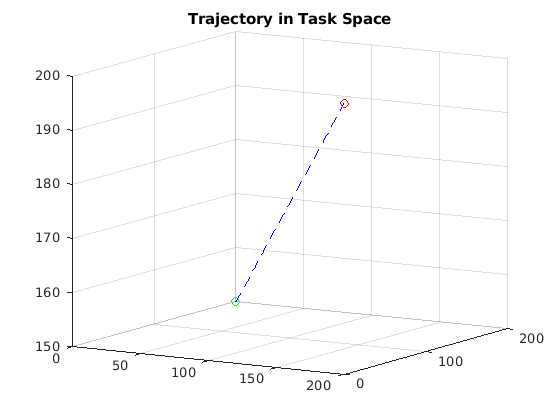

figure
title("Trajectory in Task Space")
grid on
hold on
view([31 11])

plot3(x_ti(1), x_ti(2), x_ti(3), 'og')
plot3(x_tf(1), x_tf(2), x_tf(3), 'or')

t = 0:0.1:10;

x_trajectory = 6*t.^2 - .4*t.^3;
y_trajectory = 200-6*t.^2+.4*t.^3;
z_trajectory = 150 + 1.5*t.^2 - .1*t.^3;

plot3(x_trajectory, y_trajectory, z_trajectory, '--b')

hold off

We make use of our trajectory functions to plot the positions of the end effector in the x, y, and z for the end effector using red, green, and blue respectively.

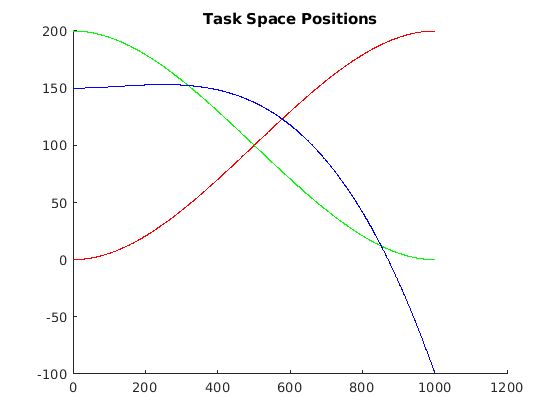

figure
title("Task Space Positions")
hold on
t = 0:.01:10;

x_trajectory = 6*t.^2 - .4*t.^3;
y_trajectory = 200-6*t.^2+.4*t.^3;
z_trajectory = 150 + 1.5*t.^2 - .4*t.^3;

plot(x_trajectory, 'r')
plot(y_trajectory, 'g')
plot(z_trajectory, 'b')

hold off;

Here we look at the velocities of the end effector in the x y and z axis with red, green, and blue respectively.

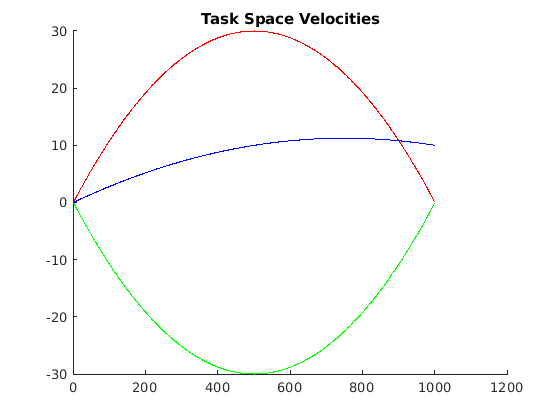

figure
title("Task Space Velocities")
hold on;

x_velocity = 12*t-1.2*t.^2;
y_velocity = -12*t+1.2*t.^2;
z_velocity = 3*t-.2*t.^2;

plot(x_velocity, 'r')
plot(y_velocity, 'g')
plot(z_velocity, 'b')

hold off;

Finally we plot the accelerations of the end effector in the x, y, and z axis with red, green, and blue respectively.

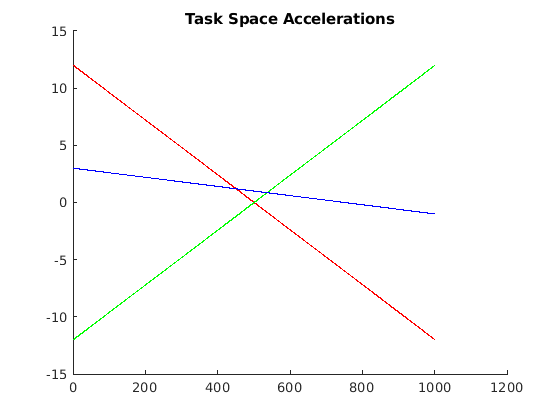

figure
title("Task Space Accelerations")
hold on;

x_acceleration = 12 - 2.4*t;
y_acceleration = -12+2.4*t;
z_acceleration = 3-.4*t;

plot(x_acceleration, 'r')
plot(y_acceleration, 'g')
plot(z_acceleration, 'b')

hold off;

Next we'll need an inverse kinematics solution to solve for arm's $q_1 ,q_2 ,\textrm{and}\;q_3$ for a given $\left(x,y,z\right)$ position of the end-effector. For instance, for our start and end positions:

q_i = inverse_kinematics(x_ti)

q_i =     0.0000
  100.0000
   50.0000


q_f = inverse_kinematics(x_tf)

q_f =     1.5708
  100.0000
   -0.0000


From here we can generate joint space positions for each point of our x y and z generated trajectories.

t = 0:0.1:10;

x_trajectory = 6*t.^2 - .4*t.^3;
y_trajectory = 200-6*t.^2+.4*t.^3;
z_trajectory = 150 + 1.5*t.^2 - .4*t.^3;

q_trajectory = zeros(3,length(t));
for step = 1:length(t)
    xyz = [x_trajectory(step); y_trajectory(step); z_trajectory(step);];
    qs = inverse_kinematics(xyz);
    q_trajectory(:,step) = qs;
end

Because $q_1$ is rotational compared to the larger moving prismatic joints, it moves a far smaller range. As such, we graph it separately to have a different axis and be more visible. 

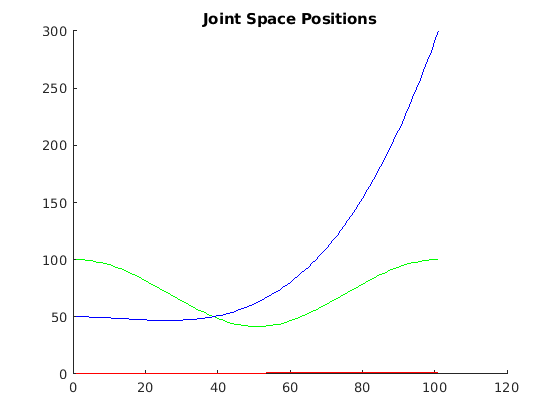

figure
title("Joint Space Positions")
hold on;

plot(q_trajectory(1,:), 'r-')
plot(q_trajectory(2,:), 'g-')
plot(q_trajectory(3,:), 'b-')

hold off;

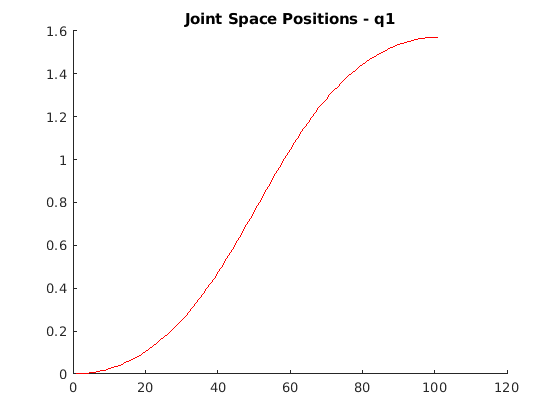


figure
title("Joint Space Positions - q1")
hold on
plot(q_trajectory(1,:), 'r-')
hold off;

Here we take the difference between each point for a given *q* to determine it's difference and thus velocity. We graph it here.

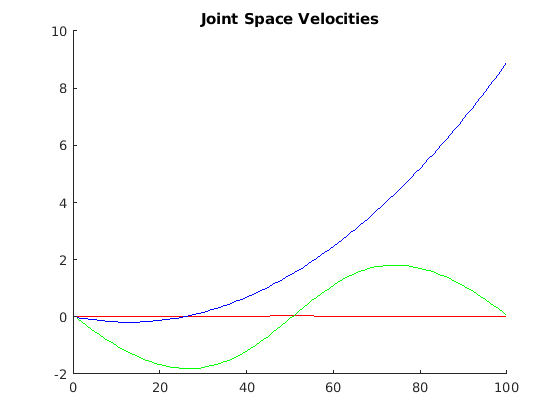

figure
title("Joint Space Velocities")
hold on;

q1_velocity = diff(q_trajectory(1,:));
q2_velocity = diff(q_trajectory(2,:));
q3_velocity = diff(q_trajectory(3,:));

plot(q1_velocity, 'r-')
plot(q2_velocity, 'g-')
plot(q3_velocity, 'b-')

hold off;

We do this again to the velocities to gain the accelerations, and plot it:

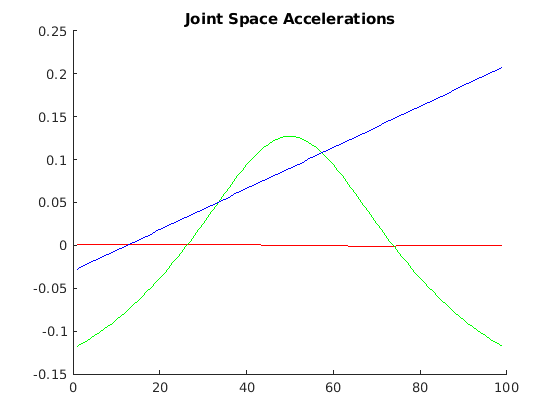

figure
title("Joint Space Accelerations")
hold on;

q1_acceleration = diff(q1_velocity);
q2_acceleration = diff(q2_velocity);
q3_acceleration = diff(q3_velocity);

plot(q1_acceleration, 'r-')
plot(q2_acceleration, 'g-')
plot(q3_acceleration, 'b-')

hold off;

## Functions

### inverse_kinematics

This function calculates the desired $q_1 ,q_2 ,\textrm{and}\;q_3$ for a given $\left(x,y,z\right)$ position of the end-effector.


$$\begin{array}{l}
z=a-c-q_3 \\
x=\cos \left(q_1 \right)\left(b+q_2 \right)\\
y=\sin \left(q_1 \right)\left(b+q_2 \right)
\end{array}$$


so therefore


$$\begin{array}{l}
q_3 =a-z-c\\
q_2 =\frac{y}{\mathrm{cos}\left(q_1 \right)}-b\\
q_1 ={\mathrm{tan}}^{-1} \left(\frac{y}{x}\right)
\end{array}$$


function q = inverse_kinematics(xyz)
    x = xyz(1) + 0.00001;
    y = xyz(2) + 0.00001;
    z = xyz(3) + 0.00001;
    a = 300;
    b = 100;
    c = 100;
    q3 = a - z - c;
    q1 = atan2(x,y);
    q2 = (y/cos(q1)) - b;
    q = [q1; q2; q3];
end

### transform_from_dh_values

This function takes a DH row with the expected valus - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.


$$H_i^0 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\theta \right) & -\mathrm{sin}\left(\theta \right) & 0 & 0\\
\mathrm{sin}\left(\theta \right) & \mathrm{cos}\left(\theta \right) & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & \mathrm{cos}\left(\alpha \right) & -\mathrm{sin}\left(\alpha \right) & 0\\
0 & \mathrm{sin}\left(\alpha \right) & \mathrm{cos}\left(\alpha \right) & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
1 & 0 & 0 & a\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


function H = transform_from_dh_values(joint)
    theta = joint.theta;
    a = joint.a;
    d = joint.d;
    alpha = joint.alpha;
    
    R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                  sin(theta)       cos(theta)     0     0;
                  0                0              1     0;
                  0                0              0     1; ];
    R_x_alpha = [ 1     0              0            0;
                  0     cos(alpha)     -sin(alpha)  0;
                  0     sin(alpha)     cos(alpha)   0;
                  0     0              0            1; ];
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

### transforms_from_dh_table

This function generates transforms between each joint frame as defined within a DH Convention table.

function Hs = transforms_from_dh_table(dh_table)
    Hs = {};
    for row = 1:length(dh_table)
        Hs{end+1} = transform_from_dh_values(dh_table(row));
    end
end

### get_base_transformations

Given a DH table, return all of the transformation matricies from the base frame 0.

function Ts = get_base_transformations(dh_table)
    Ts = {};
    transforms = transforms_from_dh_table(dh_table);
    
    for transformation=1:length(dh_table)
        Ts{end+1} = eye(4);
        for row = 1:transformation
            Ts{length(Ts)} = Ts{length(Ts)} * transforms{row};
        end
    end
end

### Get q_i_dot

Given an *i* value from 1 to 3, return the appropriate symvar theta dot for it

function qidot = get_q_i_dot(i)
    syms q1dot q2dot q3dot
    if i == 1
        qidot = q1dot;
    elseif i == 2
        qidot = q2dot;
    elseif i == 3
        qidot = q3dot;
    else
        error("i needs to be between 1 and 3");
    end
end

### Get q_i

Given an *i* value from 1 to 3, return the appropriate symvar theta for it.

function qi = get_q_i(i)
    syms q1 q2 q3;
    if i == 1
        qi = q1;
    elseif i == 2
        qi = q2;
    elseif i == 3
        qi = q3;
    else
        error("i needs to be between 1 and 6");
    end
end